clear all
A=[1.419 -0.4292;1 0];
B=[0.57;0];
C=[1 0];
D=0;
GG=ss(A,B,C,D,0.02)

GG =
 
  A = 
            x1       x2
   x1    1.419  -0.4292
   x2        1        0
 
  B = 
         u1
   x1  0.57
   x2     0
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.02 seconds
Discrete-time state-space model.



V=obsv(A,C)

V =     1.0000         0
    1.4190   -0.4292


cero=zero(GG)

cero = 0



Ahat=[A zeros(2,1);-C*A 1]

Ahat =     1.4190   -0.4292         0
    1.0000         0         0
   -1.4190    0.4292    1.0000


Bhat=[B;-C*B]

Bhat =     0.5700
         0
   -0.5700


%Especificaciones
chi=1;
ts=1.4

ts = 1.4000

sigma=4/(ts*chi)

sigma = 2.8571

wn=sigma/chi

wn = 2.8571

wd=wn*sqrt(1-chi^2)

wd = 0

%Ganancias K
T=0.02;
Polosd=[-sigma+wd*i -sigma-wd*i cero]

Polosd =    -2.8571   -2.8571         0


Polosd1=[exp(Polosd(1)*T) exp(Polosd(2)*T) cero]

Polosd1 =     0.9445    0.9445         0


K=acker(Ahat,Bhat,Polosd1)           %Ganancias controlador

K =     0.9246   -0.7530   -0.0054


%Ganancias observador
W=[B A*B]

W =     0.5700    0.8088
         0    0.5700


syms z
z1=0;
phi=(z-z1);
phi=sym2poly(phi)

phi =      1     0


phi_G=phi(1)*A +phi(2)

phi_G =     1.4190   -0.4292
    1.0000         0


A22=A;
A12=C;

chi=0.5;
ts=0.5;
sigma=4/(ts*chi)

sigma = 16

wn=sigma/chi

wn = 32

wd=wn*sqrt(1-chi^2)

wd = 27.7128

Polosd=[-sigma+wd*i -sigma-wd*i cero]

Polosd =  -16.0000 +27.7128i -16.0000 -27.7128i   0.0000 + 0.0000i


Polosd1=[exp(Polosd(1)*T) exp(Polosd(2)*T)]

Polosd1 =    0.6174 + 0.3822i   0.6174 - 0.3822i


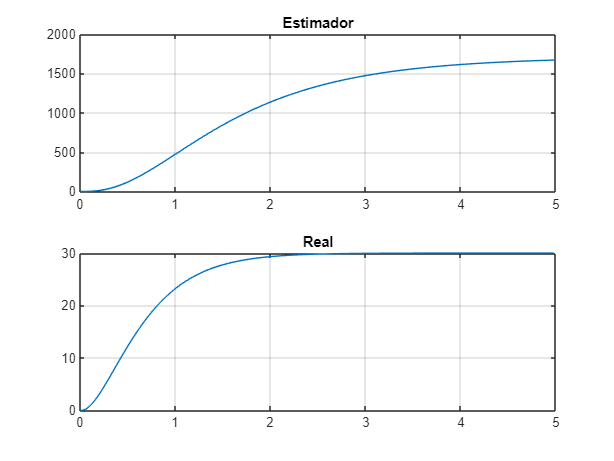

%Valores iniciales
x(:,2)=[0;0];
xest(:,2)=[0;0];
I(2)=0;

%Ajuste simulación
ts=5;   %Tiempo simulación
N=floor(ts/T);
t=0:T:N*T;
r=30*ones(1,length(t));

%Simulación
for k=2:N
    y(k)=C*x(:,k);          %Sensor
    I(k)=I(k-1)+r(k)-y(k);
    u(k)=-K(1:2)*x(:,k)-K(3)*I(k);
    xest(:,k+1)=A*xest(:,k)+B*u(k)+(y(k));
    x(:,k+1)=A*x(:,k)+B*u(k);
    subplot(2,1,1)
    plot(t(1:k),xest(1,1:k)); grid on;
    title('Estimador')
    subplot(2,1,2)
    plot(t(1:k),y(1,1:k)); grid on;
    title('Real')
end

POLO=3*-2.8571;
L=1.96;
POLO=exp(POLO*T)

POLO = 0.8425

A=[1.419 -0.4292;1 0];
B=[0.57;0];
C=[1 0];
D=0;
A11=A(1,1);
A12=A(1,2);
A21=A(2,1);
A22=A(2,2);
C1=C(1,1);
C2=C(1,2);
B1=B(1,1);
B2=B(2,1);
A0=A22-L*A12

A0 = 0.8412

B0=B2-L*B1

B0 = -1.1172

C0=A12-L*A11+A22*L-L*A12*L

C0 = -1.5616